% [robot, imInfo] = importrobot("./cad_models/version_1/RRS_2RRU_Robot/urdf/RRS_2RRU_Robot.urdf");
% [robot, imInfo] = importrobot("RRS_2RRU_Open.slx");
% show(robot,"Visuals","on");

初始化

%m
%% ver1
% R = 80*1e-3;
% r = 80*1e-3;
% L1 = 160*1e-3;
% L2 = 192*1e-3; 
% toolHight = 132*1e-3;
% z_p_min = 193.46*1e-3;

%% ver2
R = 104*1e-3;
r = 104*1e-3;
L1 = 208*1e-3;
L2 = 249.6*1e-3; 
toolHight = 136.8*1e-3;
z_p_min = 201.937*1e-3;

RRS_2RRU = RRS_2RRU_Basic(R, r, L1, L2, toolHight, z_p_min);

RRS_2RRU.z_p_max %max hight

ans = 0.4576

RRS_2RRU.z_p_operation %operation hight

ans = 0.3298

RRS_2RRU.delta_z_p %route

ans = 0.2557

分层工作空间

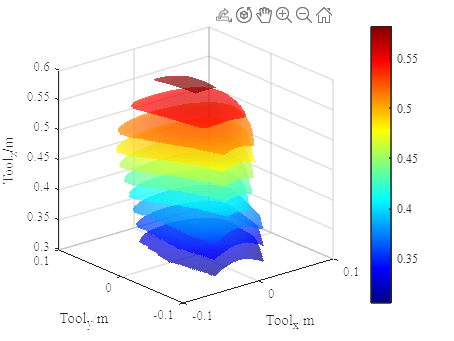

RRS_2RRU.plotToolWorkSpace([RRS_2RRU.z_p_min, RRS_2RRU.z_p_max-0.05*RRS_2RRU.delta_z_p], ...
                [-pi/6,pi/6], [-pi/6,pi/6], 10);

测试极限位姿

%[z_p, alpha, beta]
test_pose = [z_p_min, 0, 0;
            z_p_min, 0, pi/6;
            z_p_min+50*1e-3, 0, pi/6;
            z_p_min+50*1e-3, pi/6, 0;
            z_p_min+50*1e-3, -pi/6, 0;
            z_p_min+100*1e-3, 0, pi/6;
            z_p_min+100*1e-3, pi/6, 0;
            RRS_2RRU.z_p_operation, 0, pi/6;
            RRS_2RRU.z_p_operation, pi/6, 0]; 

for i=1:size(test_pose, 1)
    curPose = test_pose(i, :);
    [Tf_BTC, Tf_P] = RRS_2RRU.setEndEffectorSE3(curPose(1), curPose(2), curPose(3));
    thetas = RRS_2RRU.invKineUpdate(Tf_BTC); %invkine
    rad2deg(thetas)
end

ans =    15.0001  164.9999   15.0001


ans =     8.6395  151.3022   15.0001


ans =    18.6691  141.8553   25.0864


ans =    25.0864  154.9136   38.1447


ans =    25.0864  154.9136   18.6691


ans =    27.9585  131.5025   35.0475


ans =    35.0475  144.9525   48.4975


ans =    33.1378  124.9189   40.8400


ans =    40.8400  139.1600   55.0811
